% plant parameters
A1 = [0 1; 0 0];
B1 = [0; 1];
B2 = [0 0 0 0 0 0 0 0; 0 0 0 0 0 0 0 0];
A2 = [0 1 0 0 0 0 0 0; -1 0 0 0 0 0 0 0; 0 0 0 3 0 0 0 0; 0 0 -3 0 0 0 0 0; 
    0 0 0 0 0 5 0 0; 0 0 0 0 -5 0 0 0; 0 0 0 0 0 0 0 7; 0 0 0 0 0 0 -7 0;];
C1 = [1 0];
C2 = [-1 0];
D1 = [1 1 1 0 1 0 1 0];
D2 = [1 0 1/3 0 1/5 0 1/7 0];
sym(D1)

$$ans = \left(\begin{array}{cccccccc} 1 & 1 & 1 & 0 & 1 & 0 & 1 & 0 \end{array}\right)$$

% step 1.1: serching K1
G = [-2 2; -2 -2];
y = [1 1];
V = [y; y*G];
if rank(V) == 2
    cvx_begin sdp
        variable p(2,2)
        A1*p - p*G == B1*y;                                      %#ok<*VUNUS> 
    cvx_end
    K1 = -y*inv(p)                                                  %#ok<*MINV,NOPTS> 
end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 


K1 =     -8    -4



% step 1.2: searching L1 & L2
g = [-1.5 0 0 0 0 0 0 0 0 0;
    0 -0.5 0 0 0 0 0 0 0 0;
    0 0 -1 1 0 0 0 0 0 0;
    0 0 -1 -1 0 0 0 0 0 0;
    0 0 0 0 -2 0 0 0 0 0;
    0 0 0 0 0 -3 5 0 0 0;
    0 0 0 0 0 -5 -3 0 0 0;
    0 0 0 0 0 0 0 -3 1 0;
    0 0 0 0 0 0 0 0 -3 0;
    0 0 0 0 0 0 0 0 0 -1.2];

c = [C1 D1];
a = [A1 B2; zeros(8,2) A2];
y = [-1; -1; -1; -1; -1; -1; -1; -1; -1; -1];

% check if pair (g, y) is controllable to count l
u = rank([y g*y (g^2)*y (g^3)*y (g^4)*y (g^5)*y (g^6)*y (g^7)*y (g^8)*y (g^9)*y]);

cvx_begin sdp
    variable p(10,10)
    g*p - p*a == y*c;
cvx_end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 


l = inv(p)*y;
L1 = l(1:2) 

L1 =    -0.5838
   -0.0999


L2 = l(3:10)

L2 =    -0.3062
   -0.2652
   -0.4873
    4.3678
  -15.8071
    5.8057
   -1.7503
  -20.7748



% step 2.3: solve
cvx_begin sdp
    variable P(2,8)
    variable Y(1,8)
    P*A2 - A1*P == B1*Y + B2;
    C2*P + D2 == 0;
cvx_end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 



K2 = Y - K1*P                                                       %#ok<*NOPTS> 

K2 =     7.0000    4.0000   -0.3333    4.0000   -3.4000    4.0000   -5.8571    4.0000


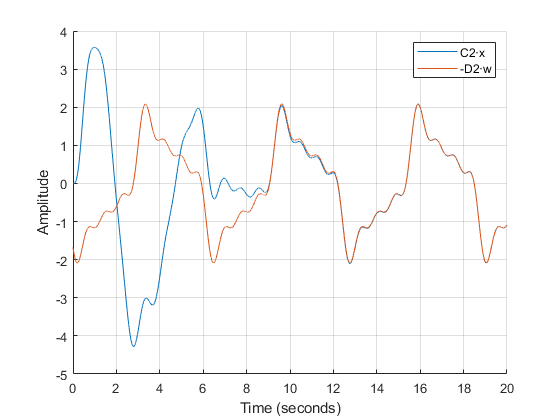

figure; %c2x -d2w
grid on;
hold on;
plot(out.C2x.Time, out.C2x.Data)
plot(out.D2w.Time, out.D2w.Data)
xlabel("Time (seconds)"), ylabel("Amplitude")
legend("C2·x","-D2·w")
xlim([0 20])

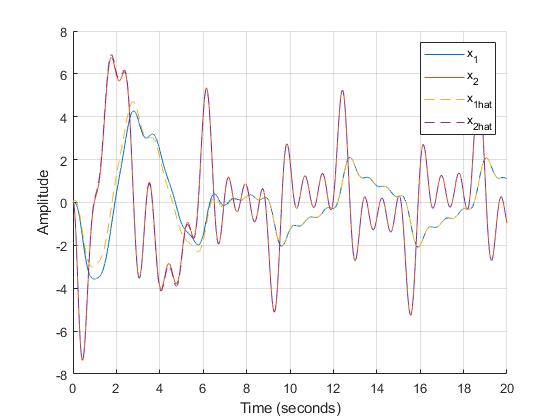

figure; %вектор состояния
grid on;
hold on;
plot(out.x.Time, out.x.Data(:, 1))
plot(out.x.Time, out.x.Data(:, 2))
plot(out.x1.Time, out.x1.Data(:, 1), "--")
plot(out.x1.Time, out.x1.Data(:, 2), "--")
xlabel("Time (seconds)"), ylabel("Amplitude")
legend("x_1","x_2","x_{1hat}","x_{2hat}")

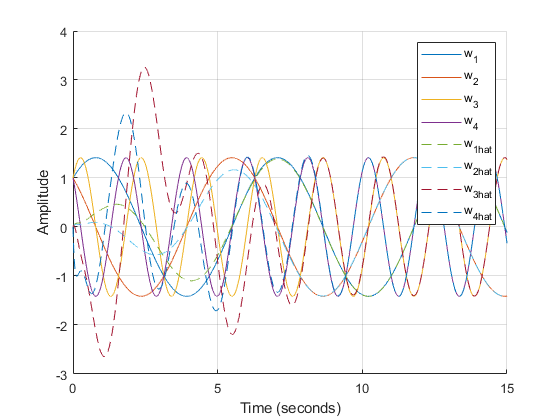

figure; %задающее воздействие
grid on;
hold on;
plot(out.ww.Time, out.ww.Data(:, 1))
plot(out.ww.Time, out.ww.Data(:, 2))
plot(out.ww.Time, out.ww.Data(:, 3))
plot(out.ww.Time, out.ww.Data(:, 4))
plot(out.w1.Time, out.w1.Data(:, 1), "--")
plot(out.w1.Time, out.w1.Data(:, 2), "--")
plot(out.w1.Time, out.w1.Data(:, 3), "--")
plot(out.w1.Time, out.w1.Data(:, 4), "--")
xlabel("Time (seconds)"), ylabel("Amplitude")
legend("w_1","w_2","w_3","w_4","w_{1hat}","w_{2hat}","w_{3hat}","w_{4hat}")
xlim([0 15])

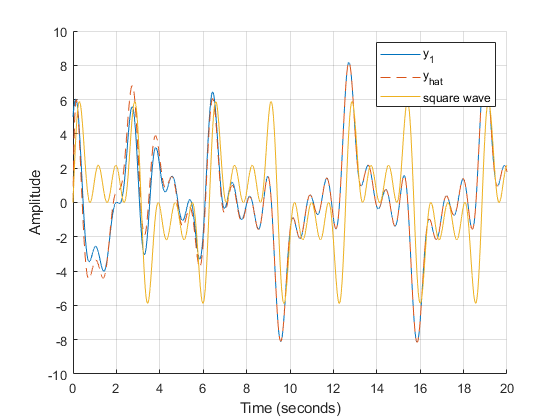

figure; %измеряемый выход
grid on;
hold on;
plot(out.y.Time, out.y.Data)
plot(out.y1.Time, out.y1.Data, "--")
plot(out.y2.Time, out.y2.Data)
xlabel("Time (seconds)"), ylabel("Amplitude")
legend("y_1","y_{hat}", "square wave")

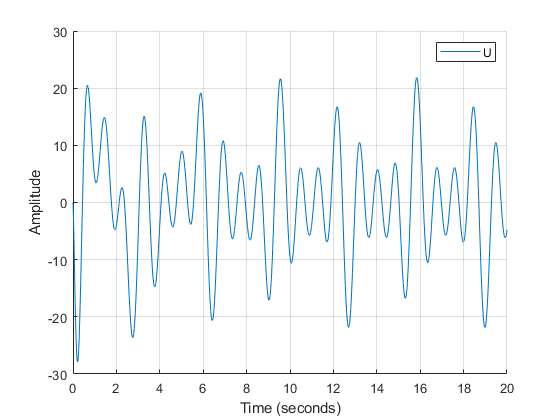

% xlim([0 40])
figure; %управляющее воздействие
grid on;
hold on;
plot(out.u.Time, out.u.Data)
xlabel("Time (seconds)"), ylabel("Amplitude")
legend("U")

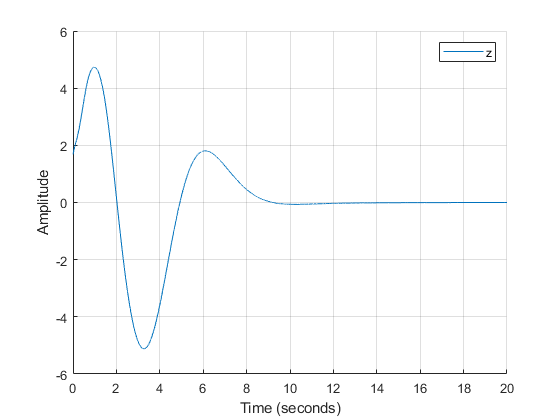

figure; %регулируемый выход
grid on;
hold on;
plot(out.z.Time, out.z.Data)
xlabel("Time (seconds)"), ylabel("Amplitude")
legend("z")